% sensor to distance in meters (curve fit)
d = @(x) 1.3501.*exp(-0.0038.*x);
% microsecond servo values to angles
a = @(x) ((x-544)./2400).*180;

load raw_data.mat
data = [deg2rad(a(raw_data(:,1))),deg2rad(a(raw_data(:,2))),d(raw_data(:,3))];

[x,y,z] = sph2cart(data(:,1),data(:,2),data(:,3));

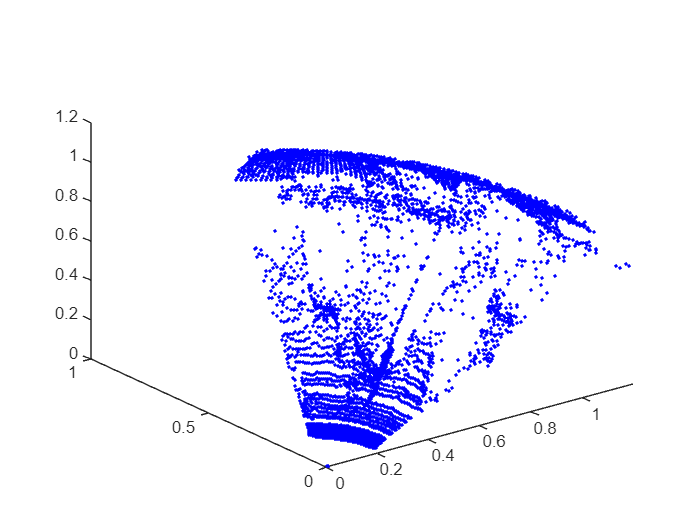

figure()
axis equal
plot3(x,y,z,'.-b','LineStyle','none')